% Generate p1
p1 = [[0,0];[0,-1];[0,-2];[0,-3]];
lin1 = [0 0.0; 0 -1].';


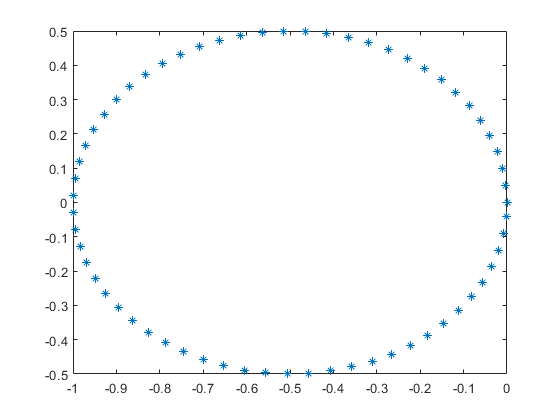

%Generate p2 using circle function at the bottom of the file
p2= -circle(-0.5,0,0.5);

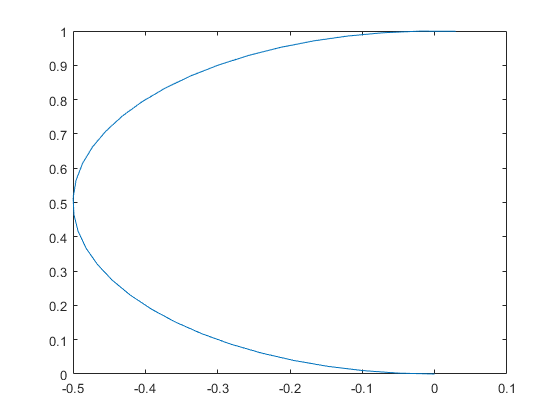

c1 = [p2(1:33,1) p2(1:33,2)]; 

plot(c1(:,2),c1(:,1))

c2 = c1(size(c1))-(lin1);  
deph = [c2(size(c2,1),1) c2(size(c2,1),2)];

c3 = deph-c1; 
deph2 = [c3(size(c3,1),1) c3(size(c3,1),2)]

deph2 =          0    0.9733


c4 = deph2+(lin1);

t = [c1;c2;c3;c4];
target = [t;t;t;t]

target =          0         0
    0.0025   -0.0499
    0.0100   -0.0993
    0.0223   -0.1478
    0.0395   -0.1947
    0.0612   -0.2397
    0.0873   -0.2823
    0.1176   -0.3221
    0.1516   -0.3587
    0.1892   -0.3917


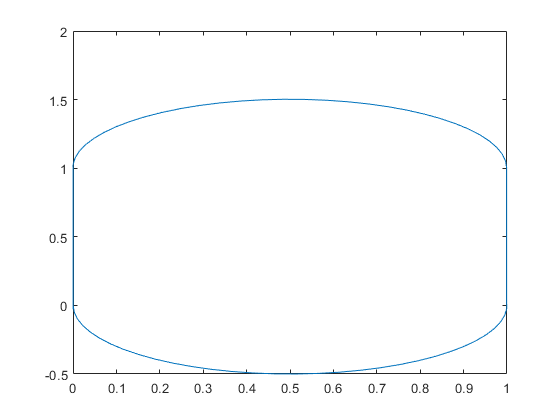

plot(target(:,1),target(:,2));

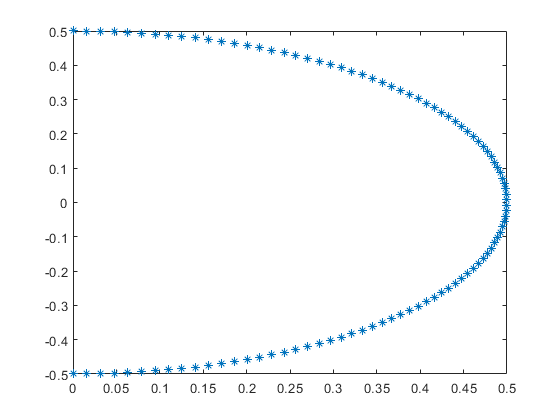

p6 =     0.0000    0.5000
    0.0159    0.4997
    0.0317    0.4990
    0.0475    0.4977
    0.0633    0.4960
    0.0790    0.4937
    0.0946    0.4910
    0.1102    0.4877
    0.1256    0.4840
    0.1409    0.4797




p6=Semicircle(0, 0, 0.5)

p7=[p6;p1;-p6;p1]

p7 =     0.0000    0.5000
    0.0159    0.4997
    0.0317    0.4990
    0.0475    0.4977
    0.0633    0.4960
    0.0790    0.4937
    0.0946    0.4910
    0.1102    0.4877
    0.1256    0.4840
    0.1409    0.4797


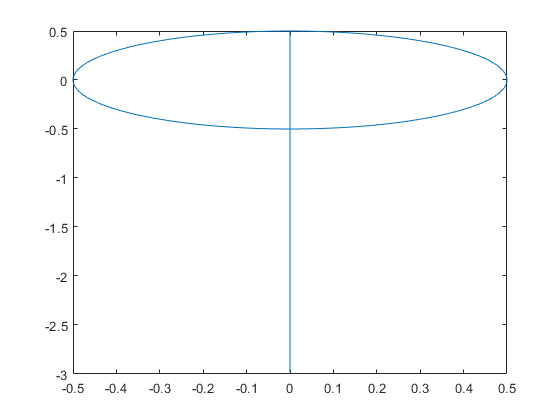

plot(p7(:,1),p7(:,2))



%p5=rectangle('Position',[3,0,2,4],'Curvature',1)

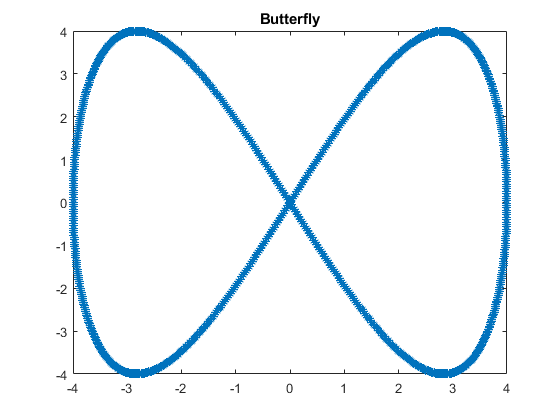

%Generate p3 and p4. 
p3 = butterfly(4, 4);

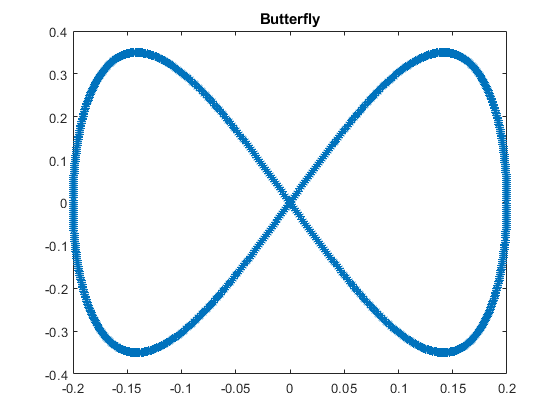

p4 = butterfly(0.35, 0.20);

function p=circle(x,y,r)
%create and plot a circle with radius r and origin (x,y)
    ang=0:0.1:pi*2; 
    xp=r*cos(ang);
    yp=r*sin(ang);
    plot(x+xp,y+yp,'*');
    p=[x+xp;y+yp]';
end
function p=butterfly(h,w)
    freq = 2*pi/30;
    Ts = 0.033; %sampling time
    t = 0:Ts:30; %simulation time
    xRef = 0 + w * sin(freq*t);
    yRef = 0 -h * sin(2*freq*t);
    plot(xRef, yRef, '*');
    title('Butterfly');
    p = [0 xRef; 0 yRef]';
end
function p=Semicircle(x,y,r)
%create and plot a circle with radius r and origin (x,y)
    th=linspace(pi/2,-pi/2,100);
    xp=r*cos(th);
    yp=r*sin(th);
    plot(x+xp,y+yp,'*');
    p=[xp;yp]';
end